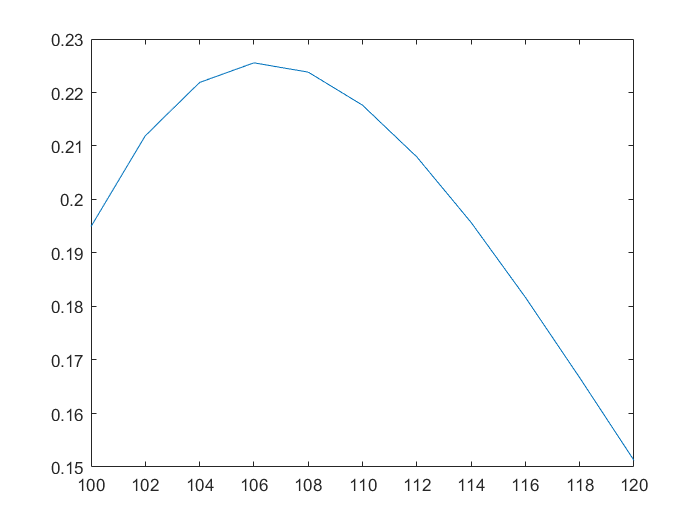

format short
sigma=0.18;
r=0.05;
T=1;
asset0=100;
K=100;
B=90;
t=0;
F=0;
stock_prices=100:2:120;
func = @(x) value(x,t,B,r,sigma,T,K);
payoff_at_t0 = arrayfun(func , stock_prices);
exact_hundred_value = payoff_at_t0(1);
plot(stock_prices, payoff_at_t0);

% we see as stock price increase, put option's payoff at t0 increase
% for some distance and then decrease. This is because when St0 is 
% small, it is likely to hit the down barrier, when St0 is larger
% it is unlikely to come below strike price at 100
Ms=1000:4000:45000;
dts = [0.02, 0.01, 0.005,0.0025];

graphlen=length(Ms)*length(dts);
MsX = zeros(graphlen, 0);
valueY = zeros(graphlen, 0);
dtslable = zeros(graphlen, 0);
ind = 1;
for i = 1:length(Ms)
    for j = 1:length(dts)
        valueY(ind)=  ValMont(asset0,dts(j),B,r,sigma,T,K,Ms(i),F);
        MsX(ind)=Ms(i);
        dtslable(ind)=dts(j);
        ind = ind+1;
    end
end

f=@(x)((x==dts(1))*1+(x==dts(2))*2+(x==dts(3))*3+(x==dts(4))*4);
c = arrayfun(f, dtslable);
% for visualization convinience, we represetn
% purple by deltaT=0.02, blue by deltaT=0.01, 
% green by DeltaT=0.005, yellow by DeltaT=0.0025
table(0.02,0.01,0.005,0.0025,'VariableNames',{'purple','blue','green', 'yellow'},'RowNames',{'timestepsize'})

ans = 1×4 table
                    purple    blue    green    yellow
                    ______    ____    _____    ______

    timestepsize     0.02     0.01    0.005    0.0025


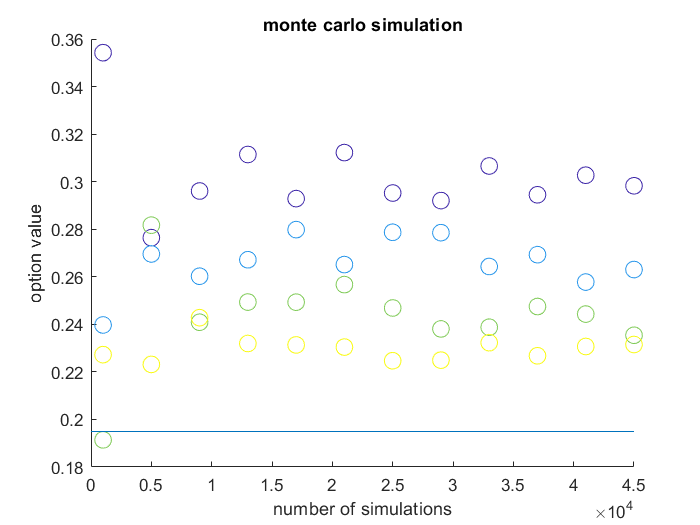


scatter(MsX,valueY, 100,c);
refline(0, exact_hundred_value);
xlabel("number of simulations");
ylabel("option value");
title("monte carlo simulation");

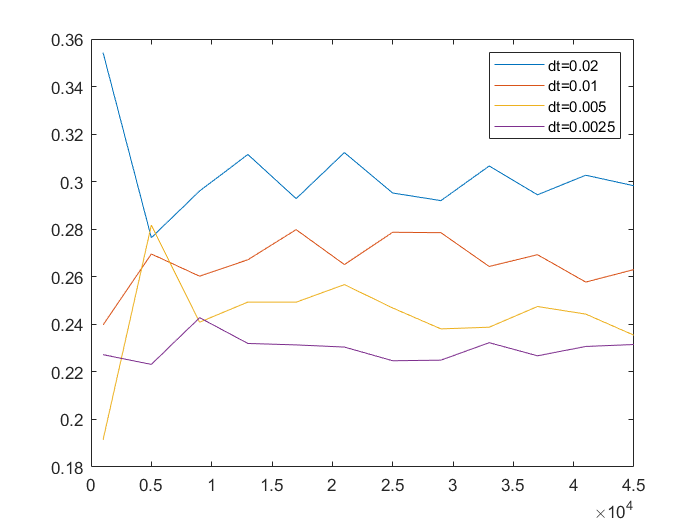


t1=dtslable==dts(1);
t2=dtslable==dts(2);
t3=dtslable==dts(3);
t4=dtslable==dts(4);
plot(MsX(t1),valueY(t1))
hold on
plot(MsX(t2),valueY(t2))
hold on
plot(MsX(t3),valueY(t3))
hold on
plot(MsX(t4),valueY(t4))
legend('dt=0.02','dt=0.01','dt=0.005','dt=0.0025')
hold off




% we observe the smaller the timestep size, the closer our esitmated value 
% to the exact estimate. Moreover, increasing number of simulation has
% little effect on accuracy.


%iv)

Not enough input arguments.

Error in a2>d1 (line 83)
    d1=(log(S/K )+(r+0.5*sigma^2)*(T-t))/(sigma*(sqrt(T-t)));

F0=transpose([0,10,20]);
option_vals = arrayfun(@(x) ValMont(asset0,0.0025,B,r,sigma,T,K,100000,x), F0);

table(F0,option_vals)
% we observe as F increase, the value of the our put option increase, it
% also looks that value increase linearly with F. This makes sense
% approximately constant propertion of simulations would reach the down
% barrier. Payoff of that constant propertion of simulations increase linearly with
% increase of F while other simulation that does not reach the barrier has
% the same expected payoff as before.


function d1 = d1(S,t,B,r,sigma,T,K)
    d1=(log(S/K )+(r+0.5*sigma^2)*(T-t))/(sigma*(sqrt(T-t)));
end

function d2 = d2(S,t,B,r,sigma,T,K)
    d2=(log(S/K )+(r-0.5*sigma^2)*(T-t))/(sigma*(sqrt(T-t)));
end

function d3 = d3(S,t,B,r,sigma,T,K)
    d3=(log(S/B )+(r+0.5*sigma^2)*(T-t))/(sigma*(sqrt(T-t)));
end

function d4 = d4(S,t,B,r,sigma,T,K)
    d4=(log(S/B )+(r-0.5*sigma^2)*(T-t))/(sigma*(sqrt(T-t)));
end

function d5 = d5(S,t,B,r,sigma,T,K)
    d5=(log(S/B )-(r-0.5*sigma^2)*(T-t))/(sigma*(sqrt(T-t)));
end

function d6 = d6(S,t,B,r,sigma,T,K)
    d6=(log(S/B )-(r+0.5*sigma^2)*(T-t))/(sigma*(sqrt(T-t)));
end

function d7 = d7(S,t,B,r,sigma,T,K)
    d7=(log(S*K/B^2)-(r-0.5*sigma^2)*(T-t))/(sigma*(sqrt(T-t)));
end

function d8 = d8(S,t,B,r,sigma,T,K)
    d8=(log(S*K/B^2)-(r+0.5*sigma^2)*(T-t))/(sigma*(sqrt(T-t)));
end

function value = value(S,t,B,r,sigma,T,K)
    value = K*exp(-r*(T-t))* ...
        (normcdf(d4(S,t,B,r,sigma,T,K))-normcdf(d2(S,t,B,r,sigma,T,K))- ...
        (B/S)^(-1+2*r/sigma^2)*(normcdf(d7(S,t,B,r,sigma,T,K))-...
        normcdf(d5(S,t,B,r,sigma,T,K)))) -S*(normcdf(d3(S,t,B,r,sigma,T,K))...
        -normcdf(d1(S,t,B,r,sigma,T,K))-...
        (B/S)^(1+2*r/sigma^2)*(normcdf(d8(S,t,B,r,sigma,T,K))...
        -normcdf(d6(S,t,B,r,sigma,T,K))));
end


function valMonte = ValMont(S,dt,B,r,sigma,T,K,m,F)
    %St(,1) first column is price at St, second column is mininum stock price
    St=ones(m,2)*S;
    n = T/dt;
    for (i = 1:n)
        St(1:m,1)=St(1:m,1).*exp((r-0.5*sigma^2)*dt+sigma*sqrt(dt)*randn(m,1));
        for (j = 1:m)
            % update minimum stock value for each simulation
            % there is no good vectorization for min/max/value_comparision
            % so we do not vectorize these
            St(j,2)=min(St(j,2),St(j,1));
        end
    end
    Vt=zeros(m,1);
    for (i = 1:m)
        if(St(i,2)<=B)
            % hit the lower bound
            Vt(i,1)=F;
        else
            Vt(i,1) = max(0, K-St(i,1));
        end        
    end
    valMonte=exp(-r*T)*(sum(Vt)/m);
end



